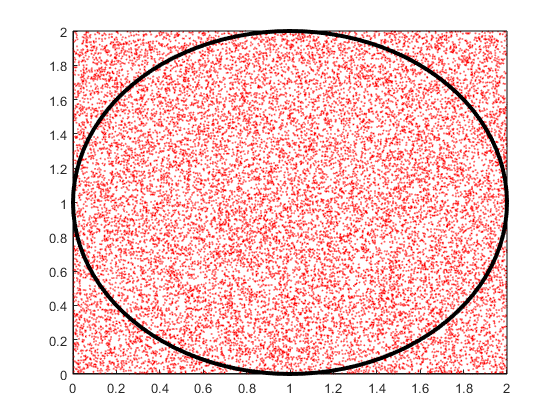

clear
figure;
hold on
circle(1,1,1);
rectangle("Position",[0,0,2,2]);
a = 2;
b = 0;

countInside = 0;
colour = "";
range = 20000;
plotarray = [];
countInsideArray =[];

for i = 1:range
    range(i) = i;
    pointx(i) = (b-a)*rand() + a;
    pointy(i) = (b-a)*rand() + a;
    
    if (withinCircle(1,1,1,pointx(i),pointy(i)) == 1)
        countInside=countInside+1;
        countInsideArray(i) = countInside; 
        colour = "b";
    else
        if(i==1)
            countInsideArray(i) = countInside;
        else
            countInsideArray(i) = countInsideArray(i-1);
        end
        colour = "g";
    end
    
end

colour = "r";
p = plot(pointx,pointy,strcat(".",colour),"MarkerSize",1);
uistack(p,"bottom")

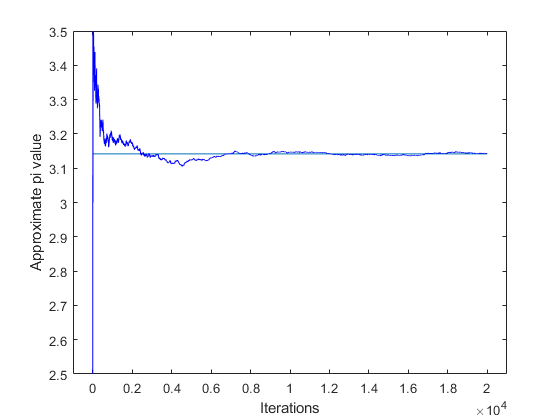


figure
plot(range,ones(1,length(range)).*pi);
hold on
plot(range,4.*(countInsideArray./range),"-b");
ylabel("Approximate pi value")
xlabel("Iterations")
xlim([-1*length(range)*0.05 length(range)*1.05])
ylim([2.5 3.5])


FinalPi = 4*(countInsideArray(length(countInsideArray))/range(length(range)))

FinalPi = 3.1428

function [tf] = withinCircle(radius,circlex,circley, x, y)
    if sqrt((x-circlex)^2 + (y-circley)^2) <= radius
        tf = 1;
    else
        tf = 0;
    end
end

function h = circle(radius,x,y)
hold on
th = 0:pi/50:2*pi;
xunit = radius * cos(th) + x;
yunit = radius * sin(th) + y;
h = plot(xunit, yunit,"k","LineWidth",3);
uistack(h,"top");
end
